# **Dissimilarity Matrices Generation & Multidimensional Scaling (MDS)**

**This script includes 5 sub-scripts : descriptive analysis, preprocessing raw data and 3 sub-scripts for the main analysis. Main analysis proceeds as follows : Firstly, It computes intra-rater reliability among participants. Secondly, it calculates intra-class correlation between participants. Finally, it generates dissimilarity matrices for the stimuli, performs Multidimensional scalling (MDS) and plots the 2D MDS images. Additionally, it identifies the 2 most distinct stimuli by computing the mean differences between all stimuli after MDS. **

### **1- Participant Demographics **

**This script computes and plots descriptive data for participant age and sex. **


clear
clc
config;
cd(demographics);
addpath(genpath(demographics));
demographics = readtable("participantDemographics_DM.xlsx");


meanAge = mean(demographics.Age);
medianAge = median(demographics.Age);
sdAge = std(demographics.Age);
youngestAge = min(demographics.Age);
oldestAge = max(demographics.Age);

% You can use tabulate function to divide the excel based on participant
% sex 


tabulate(demographics.Gender);

  Value    Count   Percent
      M        8     25.81%
      F       23     74.19%


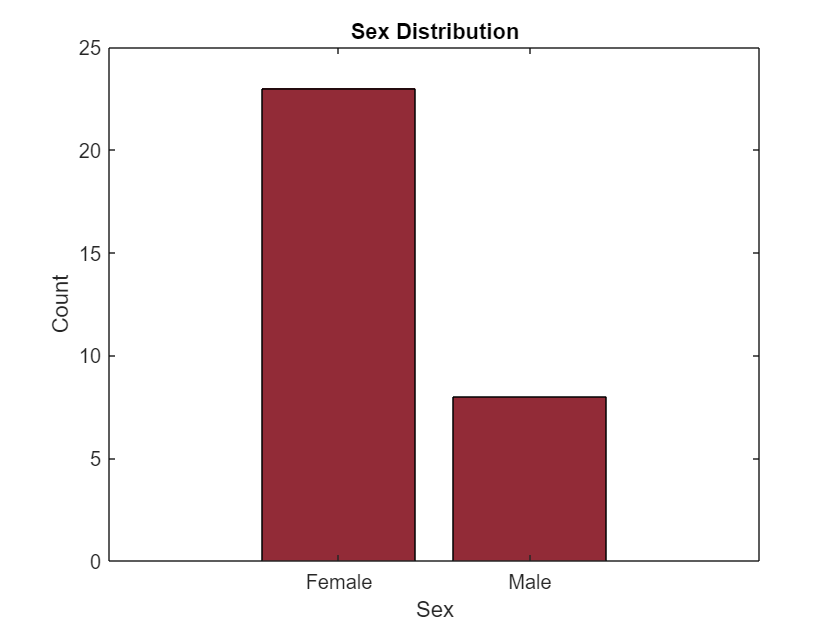


femaleAge = demographics.Age(strcmp(demographics.Gender,'F')); 
countFemale = sum((strcmp(demographics.Gender,'F')));
maleAge = demographics.Age(strcmp(demographics.Gender,'M'));
countMale = sum((strcmp(demographics.Gender,'M')));
ageTable = table({femaleAge},{maleAge},'VariableNames',{'Female Age','Male Age'});

% Plot age and sex data 

% plot sex

figure;

bar([countFemale,countMale],'FaceColor',descriptiveColor);
xlabel('Sex');
ylabel('Count');
xticklabels({'Female','Male'});
title('Sex Distribution');

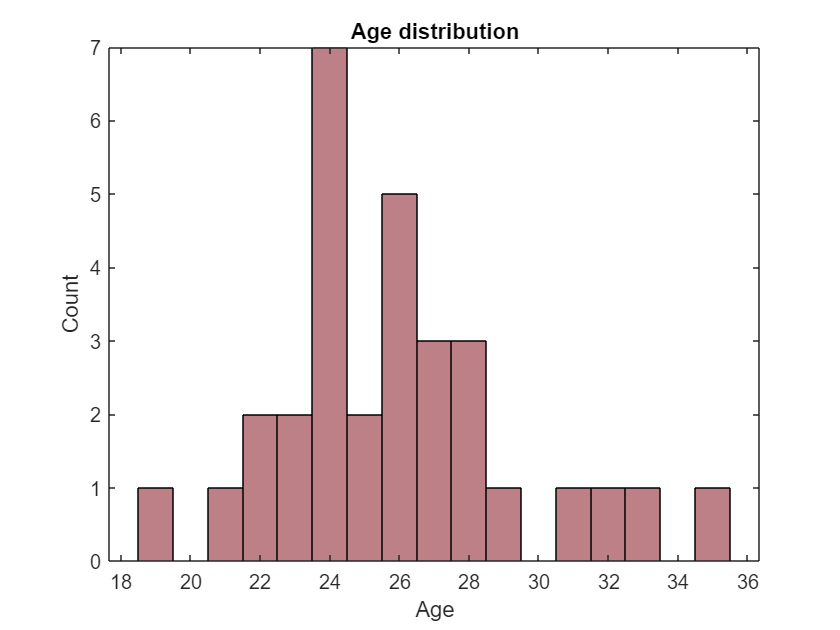


%plot age
figure;
histogram([demographics.Age],'FaceColor',descriptiveColor);
xlabel('Age');
ylabel('Count');
title('Age distribution');

## 2- Preprocessing Data 

**This script takes the raw data and generates seperate object and face files ready for the further analysis. **


clear
clc
addpath('./')
config;
cd(rawDataPath)% you should give the permission to matlab for shared folders
addpath(genpath(rawDataPath)); % data path

% Decide whether the file is object or face data
subjectFolders = dir(rawDataPath);
subjectFolders = subjectFolders([subjectFolders.isdir] & ~startsWith({subjectFolders.name}, '.') ...
                                                        & ~strcmp({subjectFolders.name},'Age&Gender')); % remove both hidden and demographics file

objectFiles = {}; %I will add the object files in this cell with participant numbers
faceFiles = {}; % I will add the face files here
trialDataFaces = {}; %for faces
trialDataObjects = {};%for objects
cleanTrialDataFaces = {}; %put clean face trial data
cleanTrialDataObject = {}; %put clean object trial data

% this goes through all the subjectFolders and cleans the data based on its
% subject group 

for i = 1:numel(subjectFolders)
    % first I open the session file that contains the info I am looking for
    
    currentSubject = fullfile(rawDataPath,subjectFolders(i).name);
    subjectFileContent = dir(currentSubject);
    subjectSessionFile = fullfile(currentSubject,'sessions.csv');
    sessionData = readtable(subjectSessionFile);
    
    if sessionData.Session_Name(1) == "sessionFace"
        faceFiles{i} = currentSubject;
        faceFiles = faceFiles(~cellfun(@isempty, faceFiles)); % get rid of empty files

            for i = 1:numel(faceFiles)
            %first I open the files here and clean the hidden files
    
            facePath = faceFiles{i};  % each facePath consist of two files: 
                              % trial and session 
     
             % access trial data 

             trialPath = fullfile(facePath,"trials.csv");
             currentTrial = readtable(trialPath);

              %clean the trial data

             Face1Block1 = rmmissing(currentTrial.RowFace1(:)); %clean the NaN values
             Face2Block1 = rmmissing(currentTrial.RowFace2(:));
             FaceBlock1Ratings = rmmissing(currentTrial.faceSimilarityBlock1(:));

            FaceMatrix1 = [Face1Block1,Face2Block1,FaceBlock1Ratings]; % first block

            FaceTable1 = array2table(FaceMatrix1, 'VariableNames', {'Face1Block1', 'Face2Block1', 'RatingsBlock1'});

            Face1Block2 = rmmissing(currentTrial.RowFace1SecondBlock(:));
            Face2Block2 = rmmissing(currentTrial.RowFace2SecondBlock(:));
            FaceBlock2Ratings = rmmissing(currentTrial.faceSimilarityBlock2);
   
            FaceMatrix2 = [Face1Block2,Face2Block2,FaceBlock2Ratings]; % second block
            FaceTable2 = array2table(FaceMatrix2,'VariableNames',{'Face1Block2','Face2Block2','RatingsBlock2'});

            cleanTrialDataFaces = horzcat(FaceTable1,FaceTable2);
    
            % match the pairs 
    
            block1Pairs = cleanTrialDataFaces {:,1:2};
            block2Pairs = cleanTrialDataFaces{:,4:5};
            ratings1 = cleanTrialDataFaces{:,3};
            ratings2 = cleanTrialDataFaces{:,6};

            [~, idx] = ismember(block1Pairs, block2Pairs, 'rows'); %finding matching pairs
   
   
            matchingRatings = [block1Pairs,ratings1,ratings2(idx)];
            RatingTable = array2table(matchingRatings,'VariableNames',{'Stimulus1','Stimulus2','RatingBlock1','RatingBlock2'});
    
            %here I also want to add subject ID. 
    
            sessionPath = fullfile(facePath,"sessions.csv");
            currentSession = readtable(sessionPath);
            subjectID = currentSession.Subject_Code;
    
                    
    
            totalRowNum = height(RatingTable);
            subjectIDRepeat = repmat({subjectID}, totalRowNum, 1);
    
            RatingTable = addvars(RatingTable, subjectIDRepeat, 'Before', 1, 'NewVariableNames', 'subjectNumber');
   
            trialDataFaces{i} = RatingTable;

            end

  elseif sessionData.Session_Name == "sessionObject"
        objectFiles{i} = currentSubject;
        objectFiles = objectFiles(~cellfun(@isempty, objectFiles));

            for i = 1:numel(objectFiles)
    
            objectPath = objectFiles{i};  
    
            % access trial data 

            trialPath = fullfile(objectPath,"trials.csv");
            currentTrial = readtable(trialPath);

            %clean the trial data

            Object1Block1 = rmmissing(currentTrial.RowNumStim1(:)); %clean the NaN values
            Object2Block1 = rmmissing(currentTrial.RowNumStim2(:));
            ObjectBlock1Ratings = rmmissing(currentTrial.ObjectSimilarityBlock1(:));

            ObjectMatrix1 = [Object1Block1,Object2Block1,ObjectBlock1Ratings]; % first block

            ObjectTable1 = array2table(ObjectMatrix1, 'VariableNames', {'Object1Block1', 'Object2Block1', 'RatingsBlock1'});

            Object1Block2 = rmmissing(currentTrial.RowObject1SecondBlock(:));
            Object2Block2 = rmmissing(currentTrial.RowObject2SecondBlock(:));
            ObjectBlock2Ratings = rmmissing(currentTrial.ObjectSimilarityBlock2(:));
   
            ObjectMatrix2 = [Object1Block2,Object2Block2,ObjectBlock2Ratings]; % second block
            ObjectTable2 = array2table(ObjectMatrix2,'VariableNames',{'Object1Block2','Object2Block2','RatingsBlock2'});

            cleanTrialDataObjects = horzcat(ObjectTable1,ObjectTable2);
            block1Pairs = cleanTrialDataObjects {:,1:2};
            block2Pairs = cleanTrialDataObjects{:,4:5};
            ratings1 = cleanTrialDataObjects{:,3};
            ratings2 = cleanTrialDataObjects{:,6};

          [~, idx] = ismember(block1Pairs, block2Pairs, 'rows'); %finding matching pairs
   
          matchingRatings = [block1Pairs,ratings1,ratings2(idx)];
          RatingTable = array2table(matchingRatings,'VariableNames',{'Stimulus1','Stimulus2','RatingBlock1','RatingBlock2'});
    
          %here I also want to add subject ID. 
         
    
         sessionPath = fullfile(objectPath,"sessions.csv");
         currentSession = readtable(sessionPath);
         subjectID = currentSession.Subject_Code;
               
              
        
        totalRowNum = height(RatingTable);
        subjectIDRepeat = repmat({subjectID}, totalRowNum, 1);
    
         RatingTable = addvars(RatingTable, subjectIDRepeat, 'Before', 1, 'NewVariableNames', 'subjectNumber');
   
        trialDataObjects{i} = RatingTable;

        end   


    end
    
end


    combinedFaceCells = vertcat(trialDataFaces{:});
    combinedObjectCells = vertcat(trialDataObjects{:});

    % I know that first participant's id is missing. This line will check
    % NaN in the final version of tables and assign a the value sub-101 

   subjectNumberCell = (combinedObjectCells.subjectNumber);
   nanIndices = cellfun(@(x) isnumeric(x) && any(isnan(x)), subjectNumberCell);
   subjectNumberCell(nanIndices) = {'Sub-101'};
   combinedObjectCells.subjectNumber = subjectNumberCell;

    %save the file
   faceRatingFile = 'FaceData.mat';
   save(fullfile(processedDataPath,faceRatingFile),'combinedFaceCells');
   objectRatingFile = 'ObjectData.mat';
   save(fullfile(processedDataPath,objectRatingFile),'combinedObjectCells');
    

## 3 - Intra-subject correlation 

**This script calculates the spearman correlation ( r ) between the similarity ratings given in the first and second blocks. Then, it fisher transforms the data and checks for the exclusion criteria ( -2 std from the group correlation mean).  **


% get the processed files 
clear
clc
config
addpath('./')
cd(processedDataPath);
load('FaceData.mat');
disp('Face')

Face


face_correlationData = combinedFaceCells;
faceIntraReliability = intra_rater_reliability(face_correlationData);

Participants you can exclude are:
Sub-119
Nobody is perfect


load('ObjectData.mat');
disp(' ')

disp('Object')

Object


object_correlationData = combinedObjectCells; % change here to do the same test for objects
objectIntraReliability = intra_rater_reliability(object_correlationData);

All is fine no one to exclude
Nobody is perfect

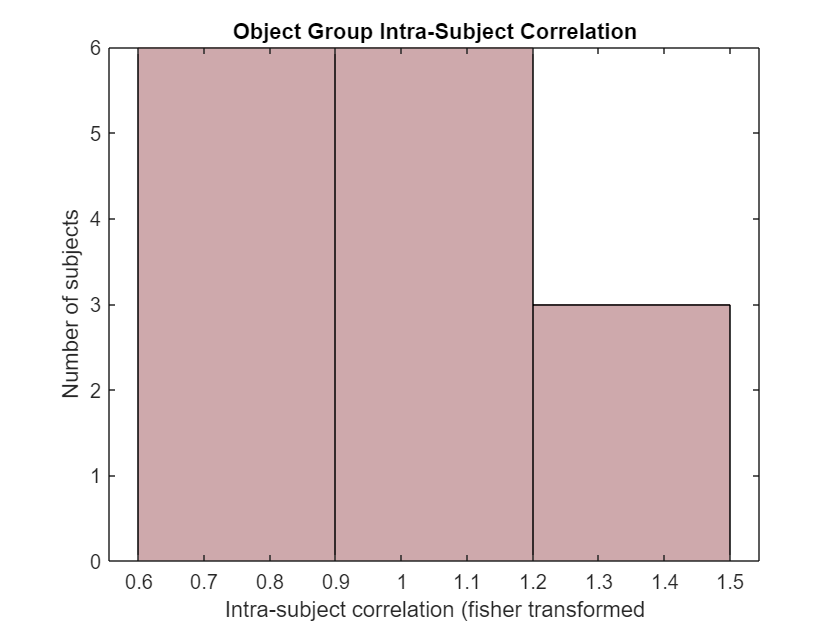


% Save the tables:
save(fullfile(processedDataPath,"faceIntraRaterReliability.mat"),'faceIntraReliability');
save(fullfile(processedDataPath,"objectIntraRaterReliability.mat"),'objectIntraReliability');

%plot the intra-rater reliability

faceIntraRater = cell2mat(faceIntraReliability(:,2));
objectIntraRater = cell2mat(objectIntraReliability (:,2));

%plot object 
figure;
histogram(objectIntraRater,'FaceColor',objectColor);
xlabel('Intra-subject correlation (fisher transformed')
ylabel('Number of subjects')
title('Object Group Intra-Subject Correlation');

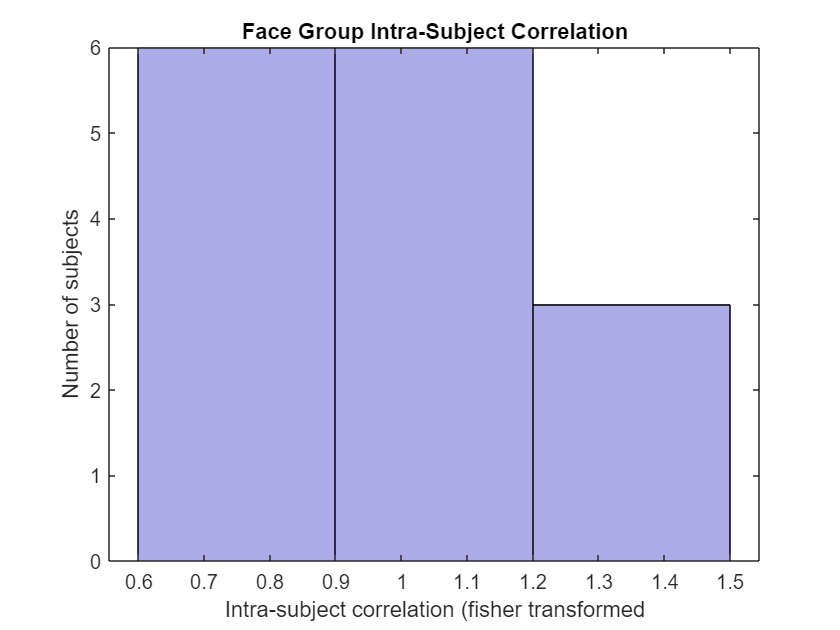


%plot face
figure;
histogram(objectIntraRater,'FaceColor',faceColor);
xlabel('Intra-subject correlation (fisher transformed')
ylabel('Number of subjects')
title('Face Group Intra-Subject Correlation');

## 4- Intra class correlation (ICC) 

**This script computes ICC and their 95% confidence intervals, with mean ratings (of two blocks) of 15 participants with consistency, two way random effects model. **


clear
clc
addpath('./')
config;
cd(processedDataPath)
addpath(genpath(processedDataPath));

% get the processed data
load('ObjectData.mat');
load('FaceData.mat');

%clean the excluded participant data before calling the function

faceAnalysisData = dataExclude(combinedFaceCells,'Sub-119');
objectAnalysisData = combinedObjectCells;

%call the intra-class correlation function
% Face:
[meanRatingsTable, faceICCTable] = intraClassCorrelationFunction(faceAnalysisData,"Face");
% Save the results:
faceICCFile = 'FaceICC.mat';
save(fullfile(processedDataPath, faceICCFile), 'faceICCTable');
faceMeanRatingFile = 'FaceMeanRatingsTable.mat';
save(fullfile(processedDataPath, faceMeanRatingFile), 'meanRatingsTable');

% Object:
[meanRatingsTable, objectICCTable] =intraClassCorrelationFunction(combinedObjectCells,"Object");

% save the files
objectICCFile = 'ObjectICC.mat';
save(fullfile(processedDataPath, objectICCFile), 'objectICCTable');
objectMeanRatingFile = 'ObjectMeanRatingsTable.mat';
save(fullfile(processedDataPath, objectMeanRatingFile), 'meanRatingsTable');

% generate table 
ICCcombinedTable = [faceICCTable;objectICCTable];
disp(ICCcombinedTable)

    DataType       ICC       LowerBound    UpperBound     FValue       DF1      DF2      pValue
    ________    _________    __________    __________    _________    _____    ______    ______

    "Face"      "0.93881"    "0.92529"     "0.95083"     "16.3419"    "189"    "2646"     "0"  
    "Object"    "0.89187"    "0.86798"     "0.91312"     "9.2482"     "189"    "2646"     "0"  



## 5 - Dissimilarity Matrix Generation and MDS 

**This script generates dissimilarity matrices and perform classical Multidimensional Scaling on non-spatial distances. It generates 2D MDS images and it identifies 2 stimuli for each group that has the highest mean distance from other stimuli.**

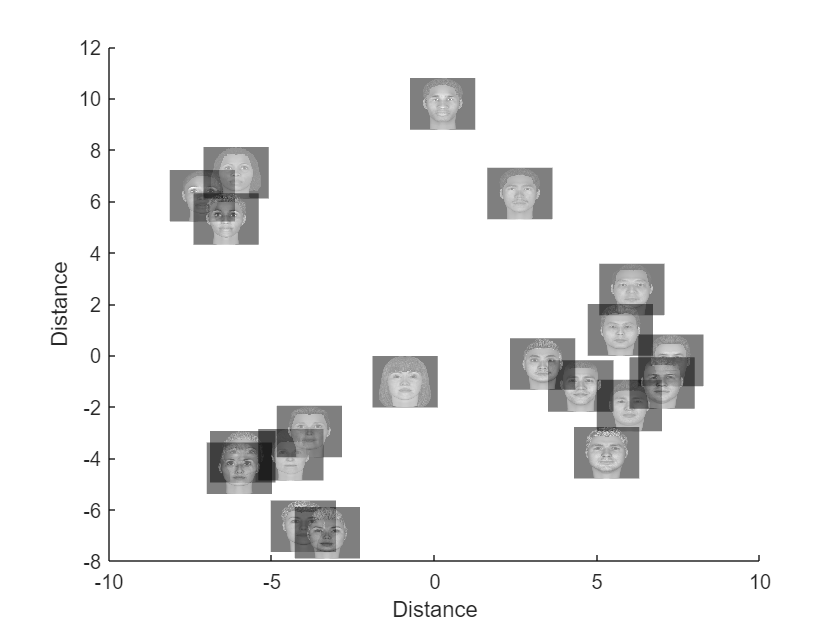


clear
clc
addpath('./');
config;

cd(processedDataPath)
addpath(genpath(processedDataPath));

%load data and compute MDS

load("FaceMeanRatingsTable.mat");
faceMeanRatingData = meanRatingsTable;
[faceDM, MDSface] = MDSFunction(faceMeanRatingData,'Face');

load("ObjectMeanRatingsTable.mat");
objectMeanRatingData = meanRatingsTable;
[objectDM, MDSobject] = MDSFunction(objectMeanRatingData,'Object');


%% MDS check for number of eigenvalues and error rate before plotting the graphs
   %check how many eigenvalues are high and how many of them are negative
   %it should be first 2 values significantly higher than others 
   eigenCheckObject = [MDSobject{2} MDSobject{2}/max(abs(MDSobject{2}))]; 
   eigenCheckFace = [MDSface{2} MDSface{2}/max(abs(MDSface{2}))];  
   
   %check the error rate --> 'error in the distances between the 2D configuration and the original distances'
   load("FaceDistanceMatrix.mat")
   faceDistanceMatrix = distanceTable;
   
   load("ObjectDistanceMatrix.mat")
   objectDistanceMatrix = distanceTable;
   
   maxrelerrFace = max(abs(table2array(faceDistanceMatrix) - squareform(pdist(MDSface{1}(:,1:2))))) / max(table2array(faceDistanceMatrix));
   maxrelerrObject = max(abs(table2array(objectDistanceMatrix) - squareform(pdist(MDSobject{1}(:,1:2))))) / max(table2array(objectDistanceMatrix));
%% Plot and save the MDS 
MDSPlot(MDSface{1},'Face');
faceMDSFigure = gcf;
filename = fullfile(plotPath, 'faceMDSFigure.png');
saveas(faceMDSFigure,filename);

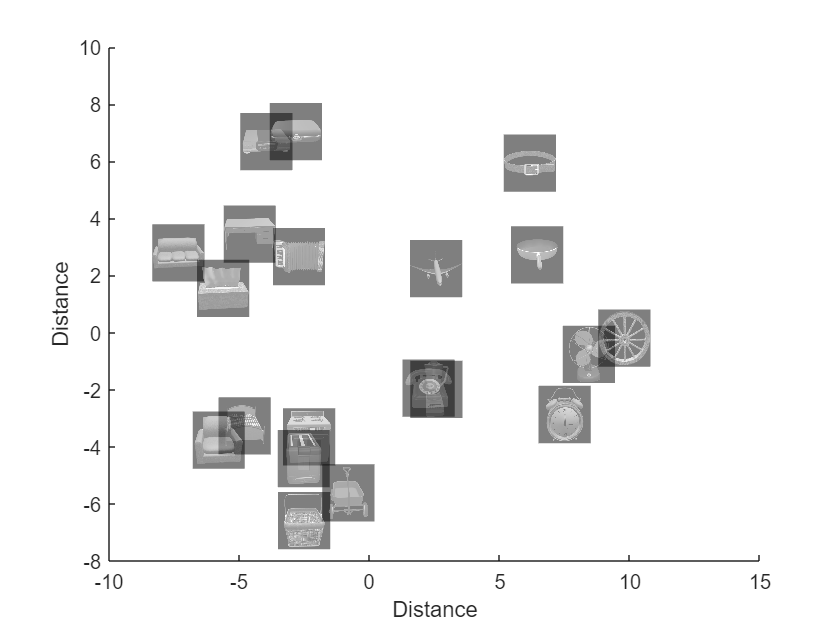


MDSPlot(MDSobject{1},'Object');
objectMDSFigure = gcf;
filename = fullfile(plotPath, 'objectMDSFigure.png');
saveas(objectMDSFigure, filename);

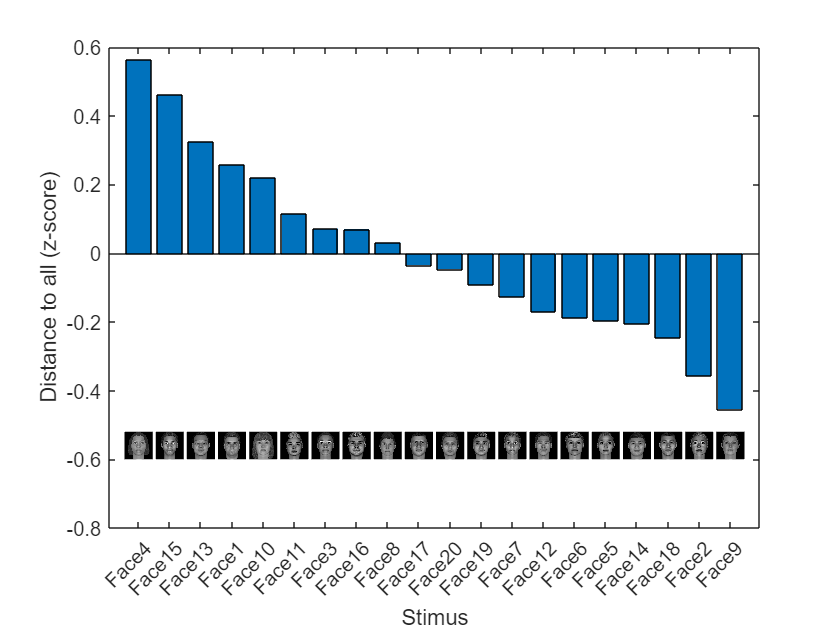


%% Select the 2 faces and objects that have the largest distance to all other stimuli:

% Set the diagonal to Nan:
faceDM(eye(length(faceDM))==1) = nan;
objectDM(eye(length(objectDM))==1) = nan;

% Compute the mean distance from each stimulus to all other:
meanFaceDist = mean(faceDM, 1, "omitnan");
meanObjectDist = mean(objectDM, 1, "omitnan");
% Compute the standard deviation:
stdFaceDist = std(faceDM, 0, "all", "omitnan");
stdObjectDist = std(objectDM, 0, "all", "omitnan");

% Normalize the distance values by the standard deviations:
normFaceDist = (meanFaceDist - mean(faceDM, "all", "omitnan")) / stdFaceDist;
normObjectDist = (meanObjectDist - mean(objectDM, "all", "omitnan")) / stdObjectDist;

% Sort by distance:
[~, sortedIndices] = sort(normFaceDist, 'descend');
% Create the list of faces ordered by their average distance to all other:
orderedFaces = {};
for i = 1:length(sortedIndices)
    orderedFaces{i} = sprintf('Face%d',  sortedIndices(i));
end
figure;
bar(orderedFaces, normFaceDist(sortedIndices))
hold on
% Add the stimuli:
imageSize = [0.9 0.08];  % Set the size of the image [x, y] in normalized units
for i = 1:length(orderedFaces)
    img = imread(orderedFaces{i} + "Center.png"); %read the images
    h = image([i-imageSize(1)/2, i+imageSize(1)/2], [-0.6, -0.6+imageSize(2)], flipud(img));
    colormap gray %grayscale the image
end
xlabel("Stimus")
ylabel("Distance to all (z-score)")

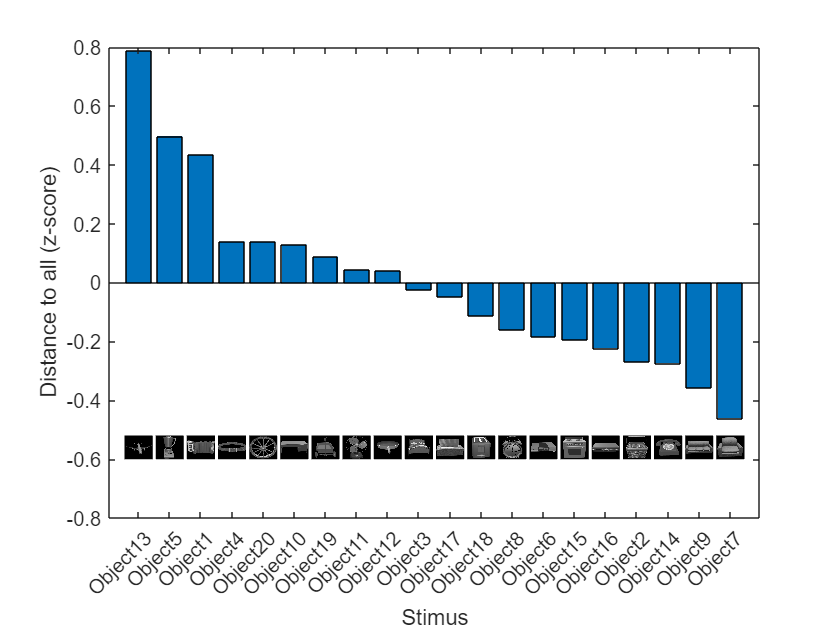



% Sort by distance:
[~, sortedIndices] = sort(normObjectDist, 'descend');
% Create the list of faces ordered by their average distance to all other:
orderedFaces = {};
for i = 1:length(sortedIndices)
    orderedObjects{i} = sprintf('Object%d',  sortedIndices(i));
end
% Create a bar plot:
figure;
bar(orderedObjects, normObjectDist(sortedIndices))
hold on
% Add the stimuli:
imageSize = [0.9 0.08];  % Set the size of the image [x, y] in normalized units
for i = 1:length(orderedObjects)
    img = imread(orderedObjects{i} + "Center.png"); %read the images
    h = image([i-imageSize(1)/2, i+imageSize(1)/2], [-0.6, -0.6+imageSize(2)], flipud(img));
    colormap gray %grayscale the image
end
xlabel("Stimus")
ylabel("Distance to all (z-score)")

### **Function Intra-rater reliability**

**This function calculates intra-rater reliability with Spearman Correlation on the similarity ratings given to the same pairs in two blocks. Then it performs Fisher transformation on the r values. It calculates mean intra-rater correlation values for face and object groups to identify Subject IDs for data exclusion. For low intra-rater reliability it prints out the participants that can be excluded which are -2std from mean. **

 function [allFishCorrelations] = intra_rater_reliability(correlationData)

correlationData.subjectNumber = cellfun(@char, correlationData.subjectNumber, 'UniformOutput', false);
subjects = unique(string(correlationData.subjectNumber)); % get unique subject numbers 

ratingPerSub = {};
spearmanCorrelation = {};
 
for i = 1:numel(subjects) % for each subject there are 210 comparisons 
    % get specific subject data 
    
    subjectData = correlationData(strcmp(correlationData.subjectNumber,subjects{i}),{'RatingBlock1', 'RatingBlock2'});
    ratingPerSub{i} = subjectData;
    
    %get specific ratings 
    Ratings = ratingPerSub{i};
    %calculate spearmanCorrelation
    correlationCoefficient = corr(Ratings.RatingBlock1,Ratings.RatingBlock2, 'Type', 'Spearman');
    spearmanCorrelation{i} = {subjects{i}, correlationCoefficient};

end
   allCorrelations = vertcat(spearmanCorrelation{:});
%% Fischer's Transformation 

fishtrans = {};
for i = 1:numel(spearmanCorrelation)
    coefficentValue = spearmanCorrelation{i}{2};
    z = 0.5 * log((1 + coefficentValue) / (1 - coefficentValue));% fischer transform code
    fishtrans{i} = {spearmanCorrelation{i}{1}, z};
end 
allFishCorrelations = vertcat(fishtrans{:});
%% Normal Distributon of my sample
secondCol = cell2mat(allFishCorrelations(:, 2));

MeanData = mean(secondCol); %to see the distribution of my data
stdData = std(secondCol);

upperLimit = MeanData + 2*stdData;
lowerLimit = MeanData - 2*stdData;

numExclude = sum(secondCol<lowerLimit);
numPerfect = sum(secondCol>upperLimit);

if numExclude > 0
    ExcludeIndex = find(secondCol<lowerLimit);
    ExcludeID = allCorrelations(ExcludeIndex);
    fprintf('Participants you can exclude are:\n');
    for i = 1:numel(ExcludeID)
     fprintf('%s\n', ExcludeID{i});
    end
else
    fprintf('All is fine no one to exclude\n')
end

% I also want to see whether we have perfectly consistent participants
% (with our definition of perfect ) 
if numPerfect > 0
    PerfectIndex = find(secondCol>upperLimit);
    PerfectID = allCorrelations(PerfectIndex);
    fprintf('Perfect participants are:\n');
    for i = 1:numel(PerfectID)
     fprintf('%s\n', PerfectID{i});
    end
else
    fprintf("Nobody is perfect")
end


 end

### Function intra-class correlation 

**This function calculates mean of 15 participants' similarity ratings per pair and applies Intra-class correlation function (Salarian, 2024) - C-k model. **

 function [meanRatingsTable, ICCTable] = intraClassCorrelationFunction(analysisData,dataType)

meanRatings = array2table(mean([analysisData.RatingBlock1,analysisData.RatingBlock2],2),"VariableNames",{'meanRatings'});
meanTable = [analysisData,meanRatings];

%combine the pairs of stimulus 

stimulusPairs = [analysisData.Stimulus1,analysisData.Stimulus2];

% Get unique pairs
uniquePairs = unique(stimulusPairs, 'rows');


meanRatingsperPair = [];

for i= 1: height(uniquePairs)
    pairIndices = all((meanTable.Stimulus1 == uniquePairs(i, 1)) & (meanTable.Stimulus2 == uniquePairs(i, 2)),2);%find the unique pairs
    pairMeanRatings = meanTable.meanRatings(pairIndices); % get the ratings for unique pairs
    meanRatingsperPair{i} = (pairMeanRatings)';
end

uniqueParticipantID =  unique(string(analysisData.subjectNumber)); 
    
% create a table that has participant ID and mean ratings given per each.
% this table is for seeing mean of how each participant rated pairs 

ratingsMatrix = [uniquePairs, cell2mat(meanRatingsperPair')];
meanRatingsTable = array2table(ratingsMatrix, 'VariableNames', ...
    [{'Stimulus1', 'Stimulus2'}, strcat(dataType,'Participant_', string(uniqueParticipantID'))]);

% calculate ICC 
%before calculating ICC, remove the identical pairs 
pairs = [meanRatingsTable{:, 1}, meanRatingsTable{:, 2}];
uniqueIdx = ~all(pairs(:, 1) == pairs(:, 2), 2);

ratingsData = table2array(meanRatingsTable(uniqueIdx, 3:end));


[r, LB, UB, F, df1, df2, p] = ICC(ratingsData, 'C-k', 0.05, 0);
ICCTable = array2table([dataType,r, LB, UB, F, df1, df2, p], ...
    'VariableNames', {'DataType','ICC', 'LowerBound', 'UpperBound', 'FValue', 'DF1', 'DF2', 'pValue'});
end

### Function Multidimensional Scaling 

**This function agregates all the ratings to generate one mean score per pair. Then it transforms the dissimilarity matrix into a distance matrix ( low similarity values represents higher distance, same pairs' distances  are fixed into 0) and converts it into a matrix format suitable for the MDS function. Finally, it applies Multidimensional Scaling. **

function [distanceMatrix, MDScell] = MDSFunction(MeanData,Datatype)

config;
meanRatingsTable = MeanData;
%Aggregate ratings into one rating with mean score given to given pair
%across participants

 rowMeans = {}; % each row consist of all the ratings given to the each pair

for i = 1:height(meanRatingsTable)
    rowMean = mean(meanRatingsTable(i,3:17),"all");
    rowMeans{i} = rowMean;
end
    rowMeans = vertcat(rowMeans{:});

% generate a table for MDS 

 stimulusTable = array2table([meanRatingsTable.Stimulus1,meanRatingsTable.Stimulus2],"VariableNames",{'Stimulus1','Stimulus2'});
 MDStable = [stimulusTable,rowMeans];

 %generate dissimilarity matrix

    stimuliIDs = unique([meanRatingsTable.Stimulus1; meanRatingsTable.Stimulus2]); % get unique stimulus IDs
    
    dissimilarityMatrix = []; % 20X20 matrix

    for i= 1:height(meanRatingsTable)

        % go through all the rows, get stimuli and their dissimilarity
        % score

        stimulus1 = MDStable.Stimulus1(i);
        stimulus2 = MDStable.Stimulus2(i);
        dissimilarityScore = MDStable.mean(i);

        % find which unique stimuli ID 

        stim1 = find(stimuliIDs == stimulus1);
        stim2 = find(stimuliIDs == stimulus2);

        dissimilarityMatrix(stim1, stim2) = dissimilarityScore;
        dissimilarityMatrix(stim2, stim1) = dissimilarityScore; % for the symetric matrix
    end

    % convert your matrix into a distance matrix 
    % higher values = longer the distance & lower values = closer the
    % distance 

 constant = max(dissimilarityMatrix(:)); % highest value 
 distanceMatrix = constant - dissimilarityMatrix;  

  coloumnNames = {};
  rowNames = {};

        for i = 1: height(distanceMatrix)
            coloumnNames{i} = ['Stimulus',num2str(i)];
            rowNames{i}=['Stimulus',num2str(i)];
        end

distanceTable = array2table(distanceMatrix,'VariableNames',coloumnNames,'RowNames',rowNames);

%save your original distance matrices

if strcmp(Datatype,'Object')
    filename = 'ObjectDistanceMatrix.mat';
elseif strcmp(Datatype,'Face')
    filename = 'FaceDistanceMatrix.mat';
end

fullPath = fullfile(processedDataPath, filename);

save(fullPath,'distanceTable')

% before computing MDS, be sure that distance between the same stimuli is 0

for i = 1:height(distanceMatrix)
            distanceMatrix(i, i) = 0;
end

%compute classic metric MDS 

MDScell = {};

if strcmp(Datatype,'Object')
    [Y, eigvals] = cmdscale(distanceMatrix); %Y = coordinates
    MDScell = {Y,eigvals,Datatype};
    
elseif strcmp(Datatype,'Face')
    [Y, eigvals] = cmdscale(distanceMatrix);
    MDScell = {Y,eigvals,Datatype};
end
    
end

### Function MDS Plot 

**This function plots the 2D MDS results. **

function[]= MDSPlot(coordinates,dataType)

config;

% load images for the plot 

Y = coordinates;

cd(faceImagesPath);
addpath(genpath(faceImagesPath));
faceImages = {'Face1Center.png','Face2Center.png','Face3Center.png','Face4Center.png','Face5Center.png','Face6Center.png' ...
            'Face7Center.png','Face8Center.png','Face9Center.png','Face10Center.png','Face11Center.png','Face12Center.png','Face13Center.png','Face14Center.png','Face15Center.png'...
            'Face16Center.png','Face17Center.png','Face18Center.png','Face19Center.png','Face20Center.png'};
cd(objectImagesPath)
addpath(genpath(faceImagesPath));
objectImages = {'Object1Center.png','Object2Center.png','Object3Center.png','Object4Center.png','Object5Center.png','Object6Center.png' ...
            'Object7Center.png','Object8Center.png','Object9Center.png','Object10Center.png','Object11Center.png','Object12Center.png','Object13Center.png','Object14Center.png','Object15Center.png'...
            'Object16Center.png','Object17Center.png','Object18Center.png','Object19Center.png','Object20Center.png'};

%specify stimulus Names 
stimulusNames = {'1','2','3','4','5','6','7','8','9','10','11','12','13','14','15','16','17','18','19','20'};

%plot images 

if strcmp(dataType,'Face')
    images = faceImages;
elseif strcmp(dataType,'Object')
    images = objectImages;
end

figure;
        xlabel('Distance')
        ylabel('Distance')
         
hold on
              
allImages = {};
for i = 1:numel(images)
currentImage = imread(images{i}); %read the images
allImages{i} = currentImage;
end


for j = 1: numel(allImages) %plot the images on the MDS coordinates

    imgData = flipud(cell2mat(allImages(j))); % Get image data
    alphaData = ones(size(imgData, 1), size(imgData, 2)) * 0.5;

image('XData',[Y(j,1)-1 Y(j,1)+1],'YData',[Y(j,2)-1 Y(j,2)+1],'CData',imgData,'AlphaData', alphaData); %rescale and flip the images
%text(Y(j,1),Y(j,2),stimulusNames{j})
hold off
end 
colormap gray %grayscale the image

end